clear;
clc;

set( groot, 'defaultLineLineWidth', 1.2 ) ; % plot line 두께 지정
set( groot, 'defaultAxesXGrid', 'on' ) ; % x축 방향으로 grid 생성
set( groot, 'defaultAxesYGrid', 'on' ) ; % y축 방향으로 grid 생성
set( groot, 'defaultAxesTitleFontSizeMultiplier', 1.5);  % Title 크기 설정
set( groot, 'defaultAxesFontSize', 12 ); % 축에 있는 글씨 크기 지정
set( groot, 'defaultAxesFontName', 'Times New Roman'); % 축에 있는 글씨 폰트 지정
set( groot, 'defaultFigureColor', 'w'); % figure 색상

% Load data
dateStr = '20250901';      % log date
runIdx  = '1';             % log nums

scriptFullPath = matlab.desktop.editor.getActiveFilename;
currentDir = fileparts(scriptFullPath);

while true
    [parentDir, folderName] = fileparts(currentDir);
    if strcmp(folderName, 'mppi_solver')
        projectRoot = currentDir;
        break;
    end
    if isempty(parentDir)
        error('Directory mppi_solver not found');
    end
    currentDir = parentDir;
end

absPath = fullfile(projectRoot, 'runs', ...
                   dateStr, runIdx, 'mppi_canadarm');

torque = h5read(fullfile(absPath, 'mppi_canadarm.mat'), '/torque');
torque_clamp = h5read(fullfile(absPath, 'mppi_canadarm.mat'), '/torque_clamp');
torque_energy = h5read(fullfile(absPath, 'mppi_canadarm.mat'), '/torque_energy');
kinetic_energy = h5read(fullfile(absPath, 'mppi_canadarm.mat'), '/kinetic_energy');

absPath = fullfile(projectRoot, 'runs', ...
                   dateStr, runIdx, 'canadarm_solver_node');
torque_debug = h5read(fullfile(absPath, 'solver_node.mat'), '/torque_debug');

clearvars dateStr runIdx scriptFullPath currentDir parentDir folderName projectRoot absPath

init_data_idx = 1;
end_data_idx = init_data_idx+2000;
torque = torque(:,init_data_idx:end_data_idx);
torque_clamp = torque_clamp(:,init_data_idx:end_data_idx);
torque_energy = torque_energy(:,init_data_idx:end_data_idx);
kinetic_energy = kinetic_energy(:,init_data_idx:end_data_idx);

torque(1,:) = torque(1,:) - torque(1,1);
torque_clamp(1,:) = torque_clamp(1,:) - torque_clamp(1,1);
torque_energy(1,:) = torque_energy(1,:) - torque_energy(1,1);
kinetic_energy(1,:) = kinetic_energy(1,:) - kinetic_energy(1,1);

torque_debug = torque_debug(:,init_data_idx:end);
torque_debug(1,:) = torque_debug(1,:) - torque_debug(1,1);

% torque_sim_time = torque(1,:);
% torque_value    = abs(torque(2:end,:));
% 
% % torque_value = func_torque_clamp(torque_value, 2332);
% 
% figure;
% hold on
% plot(torque_sim_time, torque_value);
% hold off
% title("Torque")
% xlabel("time (s)")
% ylabel("torque (Nm)")
% legend("q_1","q_2","q_3","q_4","q_5","q_6","q_7", ...
%     "Location","best",'Orientation','horizontal', 'Box','off')
% 
% torque_value_sum = sum(torque_value, 1);
% plot(torque_sim_time, torque_value_sum);

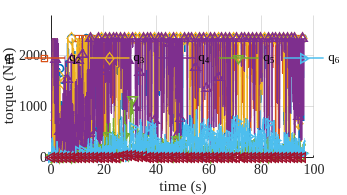

torque_clamp_sim_time = torque_clamp(1,:);
torque_clamp_value    = abs(torque_clamp(2:end,:));

f = figure('Units','pixels','WindowStyle','normal');
f.OuterPosition = [100 100 800 450];
markers = {'o','s','d','^','v','>','<'};
hold on
h = plot(torque_clamp_sim_time, torque_clamp_value);
for k = 1:numel(h)
    h(k).Marker = markers{k};
    h(k).MarkerIndices = 1:30:length(torque_clamp_sim_time);
end
hold off
xlabel("time (s)")
ylabel("torque (Nm)")
ylim([0 2800])
legend("q_1","q_2","q_3","q_4","q_5","q_6","q_7", ...
    "Location","best",'Orientation','horizontal','Box','off')

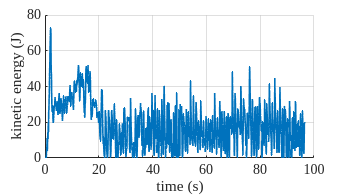

kinetic_energy_sim_time = kinetic_energy(1,:);
kinetic_energy_value    = kinetic_energy(2:end,:);


f = figure('Units','pixels','WindowStyle','normal');
f.OuterPosition = [100 100 800 450];
hold on
plot(kinetic_energy_sim_time, kinetic_energy_value);
hold off
xlabel("time (s)")
ylabel("kinetic energy (J)")

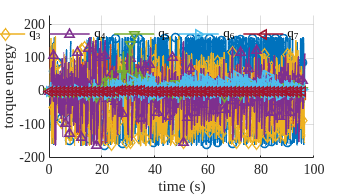

torque_energy_sim_time = torque_energy(1,:);
torque_energy_value    = torque_energy(2:end,:);

f = figure('Units','pixels','WindowStyle','normal');
f.OuterPosition = [100 100 800 450];
hold on
h2 = plot(torque_energy_sim_time, torque_energy_value);
for k = 1:numel(h)
    h2(k).Marker = markers{k};
    h2(k).MarkerIndices = 1:30:length(torque_energy_sim_time);
end
hold off
xlabel("time (s)")
ylabel("torque energy")
ylim([-200 230])
legend("q_1","q_2","q_3","q_4","q_5","q_6","q_7", ...
    "Location","north",'Orientation','horizontal','Box','off')

function tau = func_torque_clamp(tau, limit)
    tau = max(min(tau,  limit), -limit);
end

function [t_out, X_out, start_idx] = trim_start_zeros(t, X, tol)
    if nargin < 3 || isempty(tol), tol = 0; end

    t_is_row = isrow(t);
    t = t(:).';

    nz_cols = any(abs(X) > tol, 1);
    start_idx = find(nz_cols, 1, 'first');

    if isempty(start_idx)
        t_out = t - t(1);
        X_out = X;
    else
        t_out = t(start_idx:end) - t(start_idx);
        X_out = X(:, start_idx:end);
    end

    if ~t_is_row, t_out = t_out.'; end
end